# Tokaray - BenchMarking

## Benchmarking 1

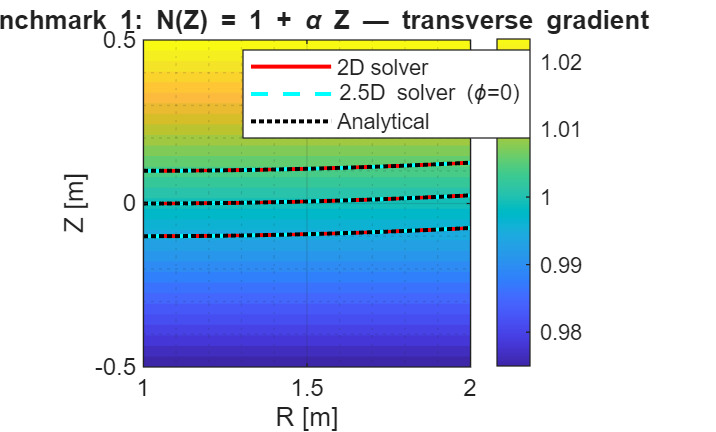

clear; clc;

% --- Common grid and solver settings

R = linspace(1, 2, 200);
Z = linspace(-0.5, 0.5, 201);

alpha = 0.05;     % refractive index gradient strength [1/m]

ds        = 0.001;  % integration step [m]
max_steps = 2000;   % maximum number of integration steps


% --- build plasma struct (N0 imposed directly, no plasma physics) ---
tk1 = tokaray();
tk1 = tk1.initialise();
tk1.config.ds        = ds;
tk1.config.max_steps = max_steps;

[tk1.plasma.R, tk1.plasma.Z] = meshgrid(R, Z);
tk1.plasma.N0 = 1 + alpha * tk1.plasma.Z;

% --- line of sight: three parallel rays launched along R ---
Z0 = [-0.1, 0, 0.1];
tk1.diag.Rin    = ones(size(Z0))*R(1);
tk1.diag.Rout   = ones(size(Z0))*R(end);
tk1.diag.Zin    = Z0;
tk1.diag.Zout   = Z0;                 % horizontal launch direction
tk1.diag.phi_in  = zeros(size(Z0));
tk1.diag.phi_out = zeros(size(Z0));
tk1.diag.th_in  = atan2(tk1.diag.Zout - tk1.diag.Zin, ...
                         tk1.diag.Rout - tk1.diag.Rin);

% --- run both isotropic solvers ---
tk1_2D  = tk1.raytracing_isotropic();
tk1_25D = tk1.raytracing_25D_isotropic();

% --- analytical solution ---
% N0_ray = 1 + alpha*Z0 (initial index at launch point)
% Z(R) = ( sqrt(N0_ray^2 + alpha^2*R^2) - 1 ) / alpha
R_ana = R;
Z_ana = zeros(length(R_ana), length(Z0));
for j = 1:length(Z0)
    N0_ray = 1 + alpha*Z0(j);
    Z_ana(:,j) = Z0(j) + ( sqrt(N0_ray^2 + alpha^2*(R_ana - tk1.diag.Rin(j)).^2) - N0_ray ) / alpha;
end

% --- plot ---
figure('Name', 'Benchmark 1 — Transverse gradient');
contourf(tk1.plasma.R, tk1.plasma.Z, tk1.plasma.N0, 30, 'LineStyle', 'none');
colorbar; hold on;
h1 = plot(tk1_2D.results.R_rt,  tk1_2D.results.Z_rt,  '-r',  'LineWidth', 1.5);
h2 = plot(tk1_25D.results.R_rt, tk1_25D.results.Z_rt, '--c', 'LineWidth', 1.5);
h3 = plot(R_ana, Z_ana, ':k', 'LineWidth', 1.5);
axis equal; grid on; grid minor;
xlabel('R [m]'); ylabel('Z [m]');
title('Benchmark 1: N(Z) = 1 + \alpha Z — transverse gradient');
legend([h1(1), h2(1), h3(1)], {'2D solver', '2.5D solver (\phi=0)', 'Analytical'}, ...
       'Location', 'best');


% --- quantitative error check (interpolate numerical Z onto R_ana grid) ---
fprintf('--- Benchmark 1: Transverse gradient ---\n');

--- Benchmark 1: Transverse gradient ---


for j = 1:length(Z0)
    Z_num_2D  = interp1(tk1_2D.results.R_rt(:,j),  tk1_2D.results.Z_rt(:,j),  R_ana, 'linear', 'extrap');
    Z_num_25D = interp1(tk1_25D.results.R_rt(:,j), tk1_25D.results.Z_rt(:,j), R_ana, 'linear', 'extrap');
    err_2D  = max(abs(Z_num_2D  - Z_ana(:,j)'));
    err_25D = max(abs(Z_num_25D - Z_ana(:,j)'));
    fprintf('  Ray %d (Z0=%.2f): max error 2D = %.2e m | 2.5D = %.2e m\n', ...
            j, Z0(j), err_2D, err_25D);
end

  Ray 1 (Z0=-0.10): max error 2D = 1.26e-05 m | 2.5D = 4.63e-05 m
  Ray 2 (Z0=0.00): max error 2D = 1.25e-05 m | 2.5D = 4.58e-05 m
  Ray 3 (Z0=0.10): max error 2D = 1.25e-05 m | 2.5D = 4.54e-05 m


## Benchmarking v2

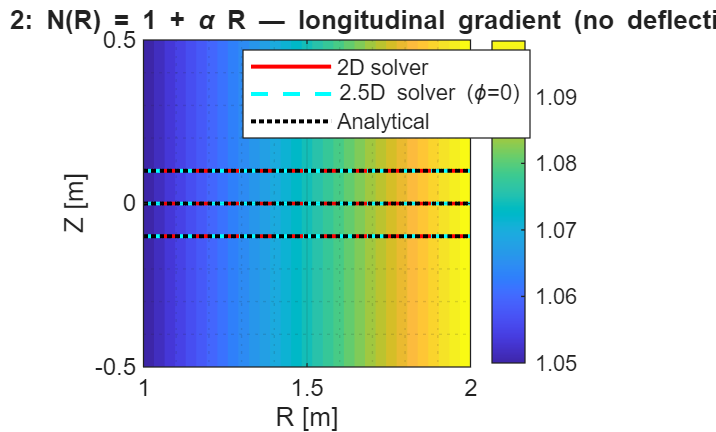

clear; clc;

% --- Common grid and solver settings
R = linspace(1, 2, 200);
Z = linspace(-0.5, 0.5, 201);

alpha = 0.05;     % refractive index gradient strength [1/m]

ds        = 0.002;  % integration step [m]
max_steps = 2000;   % maximum number of integration steps

% --- build plasma struct (N0 imposed directly, no plasma physics) ---
tk2 = tokaray();
tk2 = tk2.initialise();
tk2.config.ds        = ds;
tk2.config.max_steps = max_steps;

[tk2.plasma.R, tk2.plasma.Z] = meshgrid(R, Z);
tk2.plasma.N0 = 1 + alpha * tk2.plasma.R;

% --- line of sight: three parallel rays launched along R ---
Z0 = [-0.1, 0, 0.1];
tk2.diag.Rin     = ones(size(Z0))*R(1);
tk2.diag.Rout    = ones(size(Z0))*R(end);
tk2.diag.Zin     = Z0;
tk2.diag.Zout    = Z0;                 % horizontal launch direction
tk2.diag.phi_in  = zeros(size(Z0));
tk2.diag.phi_out = zeros(size(Z0));
tk2.diag.th_in   = atan2(tk2.diag.Zout - tk2.diag.Zin, ...
                          tk2.diag.Rout - tk2.diag.Rin);

% --- run both isotropic solvers ---
tk2_2D  = tk2.raytracing_isotropic();
tk2_25D = tk2.raytracing_25D_isotropic();

% --- analytical solution: straight line, Z(R) = Z0 ---
R_ana  = R;
Z_ana2 = repmat(Z0, length(R_ana), 1);

% --- plot ---
figure('Name', 'Benchmark 2 — Longitudinal gradient');
contourf(tk2.plasma.R, tk2.plasma.Z, tk2.plasma.N0, 30, 'LineStyle', 'none');
colorbar; hold on;
h1 = plot(tk2_2D.results.R_rt,  tk2_2D.results.Z_rt,  '-r',  'LineWidth', 1.5);
h2 = plot(tk2_25D.results.R_rt, tk2_25D.results.Z_rt, '--c', 'LineWidth', 1.5);
h3 = plot(R_ana, Z_ana2, ':k', 'LineWidth', 1.5);
axis equal; grid on; grid minor;
xlabel('R [m]'); ylabel('Z [m]');
title('Benchmark 2: N(R) = 1 + \alpha R — longitudinal gradient (no deflection)');
legend([h1(1), h2(1), h3(1)], {'2D solver', '2.5D solver (\phi=0)', 'Analytical'}, ...
       'Location', 'best');


% --- quantitative error check (deviation from straight line Z = Z0) ---
fprintf('--- Benchmark 2: Longitudinal gradient (straight ray) ---\n');

--- Benchmark 2: Longitudinal gradient (straight ray) ---


for j = 1:length(Z0)
    err_2D  = max(abs(tk2_2D.results.Z_rt(:,j)  - Z0(j)));
    err_25D = max(abs(tk2_25D.results.Z_rt(:,j) - Z0(j)));
    fprintf('  Ray %d (Z0=%.2f): max deviation 2D = %.2e m | 2.5D = %.2e m\n', ...
            j, Z0(j), err_2D, err_25D);
end

  Ray 1 (Z0=-0.10): max deviation 2D = 0.00e+00 m | 2.5D = 0.00e+00 m
  Ray 2 (Z0=0.00): max deviation 2D = 0.00e+00 m | 2.5D = 0.00e+00 m
  Ray 3 (Z0=0.10): max deviation 2D = 0.00e+00 m | 2.5D = 0.00e+00 m
